## Lab 6: MATLAB CODE AUTHOR: TOMOKI KOIKE

clear all 
close all
clc

% Loading the data files
vel_file = readmatrix('vel_calibration.xlsx');
calib_file = readmatrix('calibration.xlsx');
stand_file = rmmissing(readmatrix('stand.xlsx'));
baseball_file = rmmissing(readmatrix('baseball.xlsx'));
tennis_file = rmmissing(readmatrix("tennisball.xlsx"));
football_file = rmmissing(readmatrix("football.xlsx"));

% Setting necessary constants
rho = 1.225;  % Desity of air at standard condition [kg/m^3]
visc = 1.789*10^(-5);  % Viscosity of air at standard conditions [Pa-s]

% From velocity calibration file get the calibrated dynamic pressures and velocities 
% Dynamic pressures [Pa]
q_10to30 = vel_file(:,2)*1000; 
% Velocities 
vel_10to30 = vel_file(:,4);

% Obtain the dimensions for each object to calculate the Reynolds number
baseball_D = 0.073;  % Reference area of the baseball [m]
tennis_D = 0.064;  % Reference area of the tennis ball [m]
football_D = 0.1397;  % Short length or the diameter of the football [m]
football_L = 0.2413;  % Long length of the football [m]

% Finding the Reynolds number for each object
syms U c
Re = @(U, c) rho.*U*c/visc;
% Baseball
Re_baseball_10to30 = Re(vel_10to30, baseball_D);
% Tennis ball
Re_tennis_10to30 = Re(vel_10to30, tennis_D);
% Football short 
Re_footShort_10to30 = Re(vel_10to30, football_D);
% Football long
Re_footLong_10to30 = Re(vel_10to30, football_L);

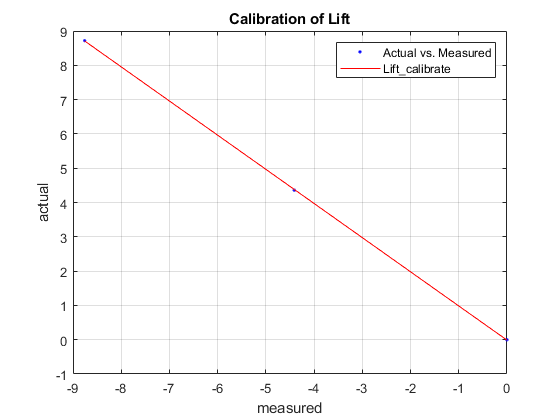

% Finding the scale factor from the lift and drag calibration
% Lift
actual_L = calib_file(:,1);
measured_L = calib_file(:,2);
% Drag
actual_D = calib_file(:,3);
measured_D = calib_file(:,4);

% Fitting the calibration data to get scale factor
% Lift
[fitresult_L, gof_L] = dataFit(measured_L, actual_L, 'lift');

disp(fitresult_L);

     Linear model Poly1:
     fitresult_L(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.9958  (-1.048, -0.9438)
       p2 =    -0.01259  (-0.3073, 0.2822)


gof_L_mat = cell2mat(struct2cell(gof_L));  % Convert structure to matrix
% Printing out the standard deviation for this polynomial
fprintf('\nThis fitted polynomial curve for lift has a STD of %.5e.', gof_L_mat(1,1));  


This fitted polynomial curve for lift has a STD of 6.43493e-04.

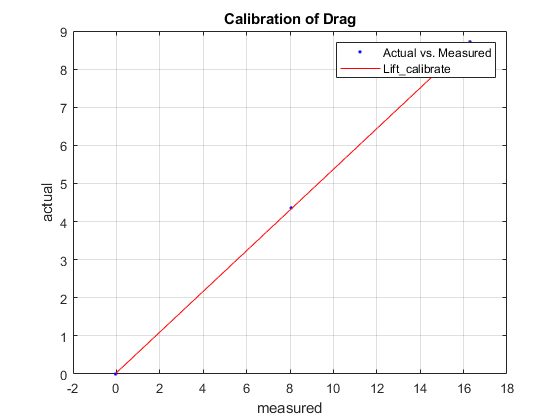

coeffs_L = coeffvalues(fitresult_L);  % Obtaining the coefficients

a_L = coeffs_L(1);
b_L = coeffs_L(2);

% Drag
[fitresult_D, gof_D] = dataFit(measured_D, actual_D, 'drag');

disp(fitresult_D);

     Linear model Poly1:
     fitresult_D(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.5339  (0.4984, 0.5694)
       p2 =     0.03209  (-0.3401, 0.4043)


gof_D_mat = cell2mat(struct2cell(gof_D));  % Convert structure to matrix
% Printing out the standard deviation for this polynomial
fprintf('\nThis fitted polynomial curve for drag has a STD of %.5e.', gof_D_mat(1,1));  


This fitted polynomial curve for drag has a STD of 1.03868e-03.

coeffs_D = coeffvalues(fitresult_D);  % Obtaining the coefficients

a_D = coeffs_D(1);
b_D = coeffs_D(2);

% Defining a equation expression for lift and drag scaling
% Lift
syms lift 
scale_lift = @(lift) a_L*lift + b_L;
% Drag
syms drag
scale_drag = @(drag) a_D*drag + b_D;

% Calculating each drag
% Stand - vertical orientation
stand_vert_drag = scale_drag(lb2N(stand_file(1:5,3)));  
% Stand - sideways orientation
stand_side_drag = scale_drag(lb2N(stand_file(6:8,3)));

% Baseball
% First measurement
baseball_drag1 = scale_drag(lb2N(baseball_file(1:5,3))) - stand_vert_drag;
% Second measurement
baseball_drag2 = scale_drag(lb2N(baseball_file(6:10,3))) - stand_vert_drag;
% Average 
baseball_drag_avg = (baseball_drag1 + baseball_drag2)./2;

% Tennis ball
% First measurement
tennis_drag1 = scale_drag(lb2N(tennis_file(1:5,3))) - stand_vert_drag;
% Second measurement
tennis_drag2 = scale_drag(lb2N(tennis_file(6:10,3))) - stand_vert_drag;
% Average 
tennis_drag_avg = (tennis_drag1 + tennis_drag2)./2;

% Football - vertical orientation 
football_vert_drag = scale_drag(lb2N(football_file(1:5,3))) - stand_vert_drag;
% Football - sideways orientation 
football_side_drag = scale_drag(lb2N(football_file(6:8,3))) - stand_side_drag;

% Calculating each drag coefficient 
% Baseball
Cd_baseball1 = calDragCoeff(baseball_drag1, q_10to30, baseball_D^2*pi/4);
Cd_baseball2 = calDragCoeff(baseball_drag2, q_10to30, baseball_D^2*pi/4);
Cd_baseball_avg = calDragCoeff(baseball_drag_avg, q_10to30, baseball_D^2*pi/4);

% Tennis ball
Cd_tennis1 = calDragCoeff(tennis_drag1, q_10to30, tennis_D^2*pi/4);
Cd_tennis2 = calDragCoeff(tennis_drag2, q_10to30, tennis_D^2*pi/4);
Cd_tennis_avg = calDragCoeff(tennis_drag_avg, q_10to30, tennis_D^2*pi/4);

% Football - vertical orientation 
Cd_football_vert = calDragCoeff(football_vert_drag, q_10to30, football_D);
Cd_football_side = calDragCoeff(football_side_drag, q_10to30(1:3), football_L);

% Calculating each lift 
% Stand - vertical orientation
stand_vert_lift = scale_lift(lb2N(stand_file(1:5,4)));  
% Stand - sideways orientation
stand_side_lift = scale_lift(lb2N(stand_file(6:8,4)));

% Baseball
% First measurement
baseball_lift1 = scale_lift(lb2N(baseball_file(1:5,4))) - stand_vert_lift;
% Second measurement
baseball_lift2 = scale_lift(lb2N(baseball_file(6:10,4))) - stand_vert_lift;
% Average 
baseball_lift_avg = (baseball_lift1 + baseball_lift2)./2;

% Tennis ball
% First measurement
tennis_lift1 = scale_lift(lb2N(tennis_file(1:5,4))) - stand_vert_lift;
% Second measurement
tennis_lift2 = scale_lift(lb2N(tennis_file(6:10,4))) - stand_vert_lift;
% Average 
tennis_lift_avg = (tennis_lift1 + tennis_lift2)./2;

% Football - vertical orientation 
football_vert_lift = scale_lift(lb2N(football_file(1:5,4))) - stand_vert_lift;
% Football - sideways orientation 
football_side_lift = scale_lift(lb2N(football_file(6:8,4))) - stand_side_lift;

% Calculating each lift coefficient 
% Baseball
Cl_baseball1 = calLiftCoeff(baseball_lift1, q_10to30, baseball_D^2*pi/4);
Cl_baseball2 = calLiftCoeff(baseball_lift2, q_10to30, baseball_D^2*pi/4);
Cl_baseball_avg = calLiftCoeff(baseball_lift_avg, q_10to30, baseball_D^2*pi/4);

% Tennis ball
Cl_tennis1 = calLiftCoeff(tennis_lift1, q_10to30, tennis_D^2*pi/4);
Cl_tennis2 = calLiftCoeff(tennis_lift2, q_10to30, tennis_D^2*pi/4);
Cl_tennis_avg = calLiftCoeff(tennis_lift_avg, q_10to30, tennis_D^2*pi/4);

% Football - vertical orientation 
Cl_football_vert = calLiftCoeff(football_vert_lift, q_10to30, football_D);
Cl_football_side = calLiftCoeff(football_side_lift, q_10to30(1:3), football_L);

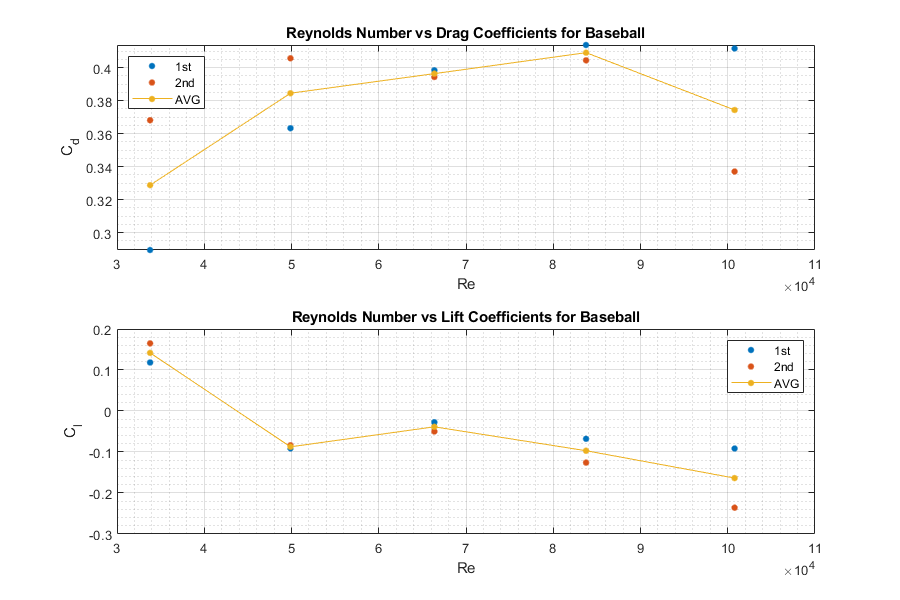

% Plotting
% Baseball
% Drag
fig1 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
subplot(2,1,1)
plot(Re_baseball_10to30, Cd_baseball1, '.', 'MarkerSize', 15)
title('Reynolds Number vs Drag Coefficients for Baseball')
xlabel('Re')
ylabel('C_d')
hold on 
plot(Re_baseball_10to30, Cd_baseball2, '.', 'MarkerSize', 15)
plot(Re_baseball_10to30, Cd_baseball_avg, '.-', 'MarkerSize', 15)
hold off
grid on
grid minor
box on
legend('1st', '2nd', 'AVG', 'Location', 'northwest')
% Lift
subplot(2,1,2)
plot(Re_baseball_10to30, Cl_baseball1, '.', 'MarkerSize', 15)
title('Reynolds Number vs Lift Coefficients for Baseball')
xlabel('Re')
ylabel('C_l')
hold on 
plot(Re_baseball_10to30, Cl_baseball2, '.', 'MarkerSize', 15)
plot(Re_baseball_10to30, Cl_baseball_avg, '.-', 'MarkerSize', 15)
hold off 
grid on
grid minor
box on
legend('1st', '2nd', 'AVG')
saveas(fig1, 'baseball_result.png')

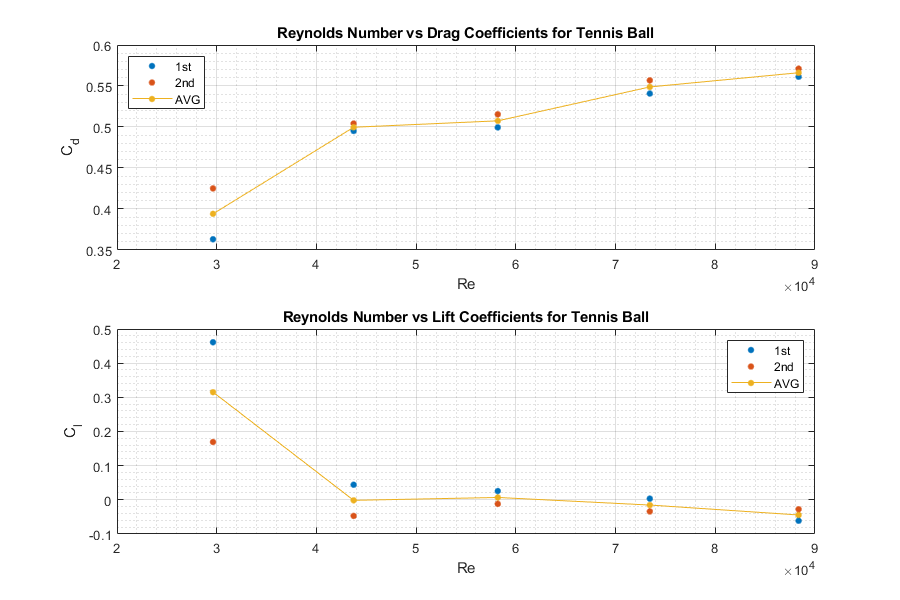

% Tennis Ball
% Drag
fig2 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
subplot(2,1,1)
plot(Re_tennis_10to30, Cd_tennis1, '.', 'MarkerSize', 15)
title('Reynolds Number vs Drag Coefficients for Tennis Ball')
xlabel('Re')
ylabel('C_d')
hold on 
plot(Re_tennis_10to30, Cd_tennis2, '.', 'MarkerSize', 15)
plot(Re_tennis_10to30, Cd_tennis_avg, '.-', 'MarkerSize', 15)
hold off
grid on
grid minor
box on
legend('1st', '2nd', 'AVG', 'Location', 'northwest')
% Lift
subplot(2,1,2)
plot(Re_tennis_10to30, Cl_tennis1, '.', 'MarkerSize', 15)
title('Reynolds Number vs Lift Coefficients for Tennis Ball')
xlabel('Re')
ylabel('C_l')
hold on 
plot(Re_tennis_10to30, Cl_tennis2, '.', 'MarkerSize', 15)
plot(Re_tennis_10to30, Cl_tennis_avg, '.-', 'MarkerSize', 15)
hold off 
grid on
grid minor
box on
legend('1st', '2nd', 'AVG')
saveas(fig2, 'tennis_result.png')

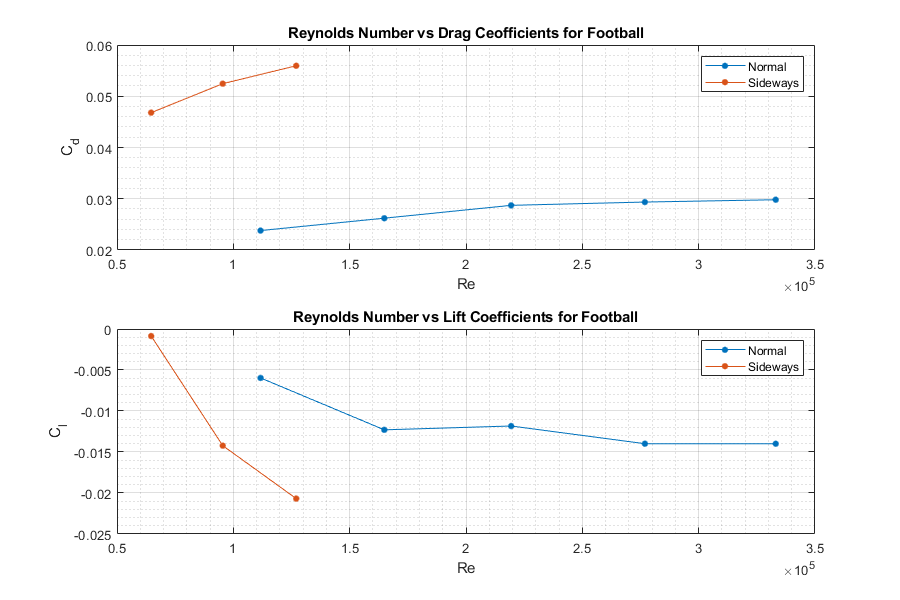

% Football
% Drag
fig3 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
subplot(2,1,1)
plot(Re_footLong_10to30, Cd_football_vert, '.-', 'MarkerSize', 15)
title('Reynolds Number vs Drag Ceofficients for Football')
xlabel('Re')
ylabel('C_d')
hold on 
plot(Re_footShort_10to30(1:3), Cd_football_side, '.-', 'MarkerSize', 15)
hold off
grid on
grid minor
box on
legend('Normal', 'Sideways', 'Location', 'northeast')
% Lift
subplot(2,1,2)
plot(Re_footLong_10to30, Cl_football_vert, '.-', 'MarkerSize', 15)
title('Reynolds Number vs Lift Coefficients for Football')
xlabel('Re')
ylabel('C_l')
hold on 
plot(Re_footShort_10to30(1:3), Cl_football_side, '.-', 'MarkerSize', 15)
hold off 
grid on
grid minor
box on
legend('Normal', 'Sideways', 'Location', 'northeast')
saveas(fig3, 'football_result.png')

### FUNCTIONS

function [fitresult, gof] = dataFit(measured, actual, type)
    %DATAFIT(MEASURED,ACTUAL)
    %  Create a fit.
    %
    %  Data for 'Lift_calibrate' fit:
    %      X Input : measured_L
    %      Y Output: actual_L
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %% Fit: 'Lift_calibrate'.
    [xData, yData] = prepareCurveData( measured, actual);
    
    % Set up fittype and options.
    ft = fittype( 'poly1' );
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft );
    
    % Plot fit with data.
    figure( 'Name', 'Lift_calibrate' );
    h = plot( fitresult, xData, yData );
    if type == 'lift'
        title('Calibration of Lift')
    else
        title('Calibration of Drag')
    end
    legend( h, 'Actual vs. Measured', 'Lift_calibrate', 'Location',...
        'NorthEast', 'Interpreter', 'none' );
    % Label axes
    xlabel( 'measured', 'Interpreter', 'none' );
    ylabel( 'actual', 'Interpreter', 'none' );
    grid on
end

function Cd = calDragCoeff(D, dynP, l)
    % Function to compute the drag coefficient 
    Cd = D./dynP/l;
end

function Cl = calLiftCoeff(L, dynP, l)
    % Function to compute the lift coefficient 
    Cl = L./dynP/l;
end

function F = lb2N(f)
    % Function to convert pounds to Newtons
    F = f ./ 0.22480894244318;
end
